# ThermoeconomicModel demo

Analyze an ORC system with IHE (*rorc_model*) using the base function ThermoeconomicModel

#### **Create the Thermoeconomic Model**

the data file and create the model with some parameters. 

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
model=ThermoeconomicModel(filename,...
    'CostTables','ALL',...
    'DiagnosisMethod','WASTE_INTERNAL',...
    'Debug',false);

#### **Show the results for Reference State**

Print the result tables and show ICT and waste allocation graphs

model.showResults;


Flows Definition Table - REF

  Id Key   From    To      Type      
——————————————————————————————————————
   1 B1    BLR_P1  TRB_F1  INTERNAL  
   2 B2    TRB_F1  IHE_F1  INTERNAL  
   3 B3    IHE_F1  CND_F1  INTERNAL  
   4 B4    CND_F1  PMP_P1  INTERNAL  
   5 B5    PMP_P1  IHE_P1  INTERNAL  
   6 B6    IHE_P1  BLR_P1  INTERNAL  
   7 QBLR  ENV_R1  BLR_F1  RESOURCE  
   8 WP    TRB_P1  PMP_F1  INTERNAL  
   9 WN    TRB_P1  ENV_O1  OUTPUT    
  10 QCND  CND_P1  ENV_W1  WASTE     


Productive Groups Definition Table - REF

  Id Key     Definition  Type      
————————————————————————————————————
   1 BLR_F1  QBLR        FUEL      
   2 BLR_P1  B1-B6       PRODUCT   
   3 TRB_F1  B1-B2       FUEL      
   4 TRB_P1  WN+WP       PRODUCT   
   5 IHE_F1  B2-B3       FUEL      
   6 IHE_P1  B6-B5       PRODUCT   
   7 PMP_F1  WP          FUEL      
   8 PMP_P1  B5-B4       PRODUCT   
   9 CND_F1  B3-B4       FUEL      
  10 CND_P1  QCND        PRODUCT   
  11 ENV_R1  QBLR        RESOURCE  

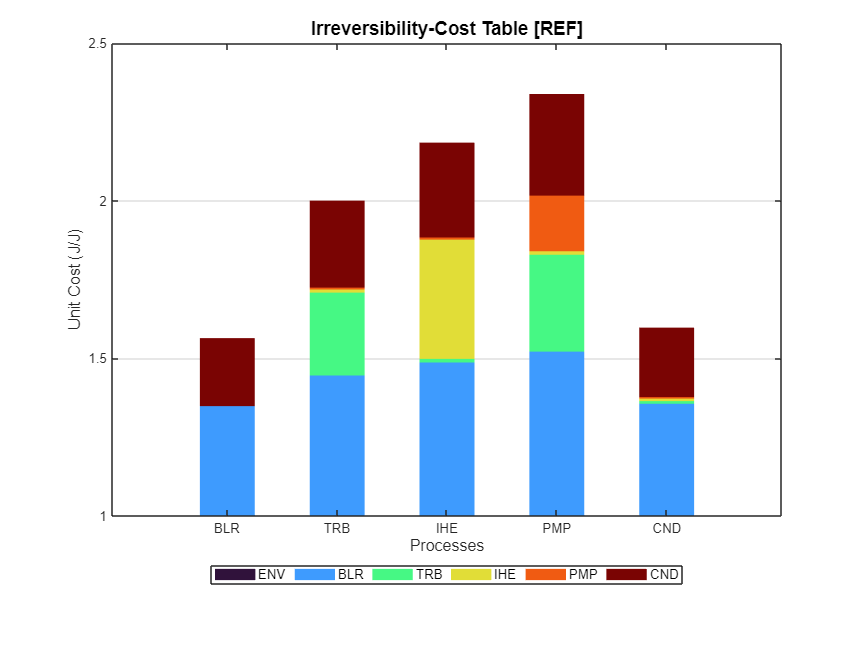

showGraph(model,cType.Tables.PROCESS_ICT);

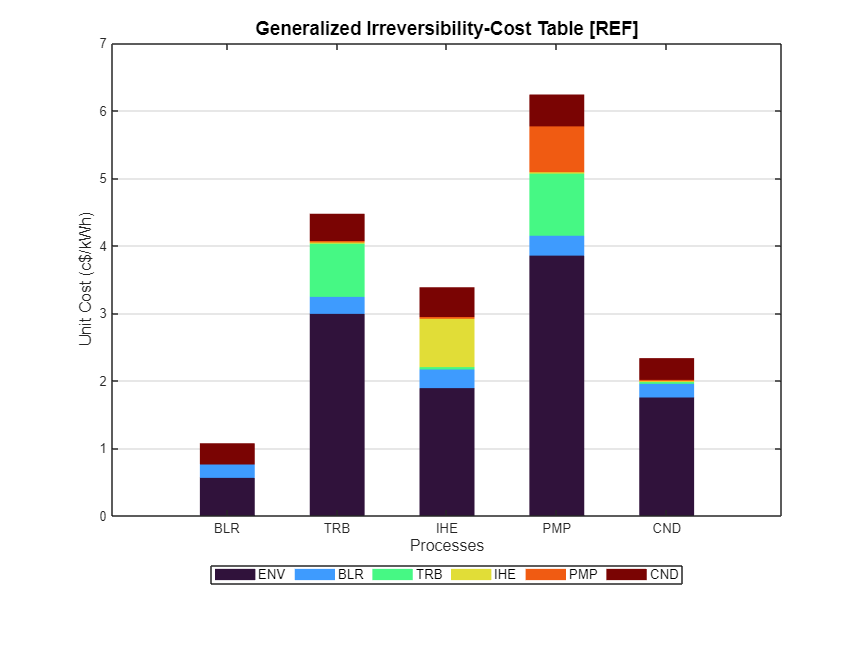

ShowGraph(model,'Graph',cType.Tables.PROCESS_GENERAL_ICT);

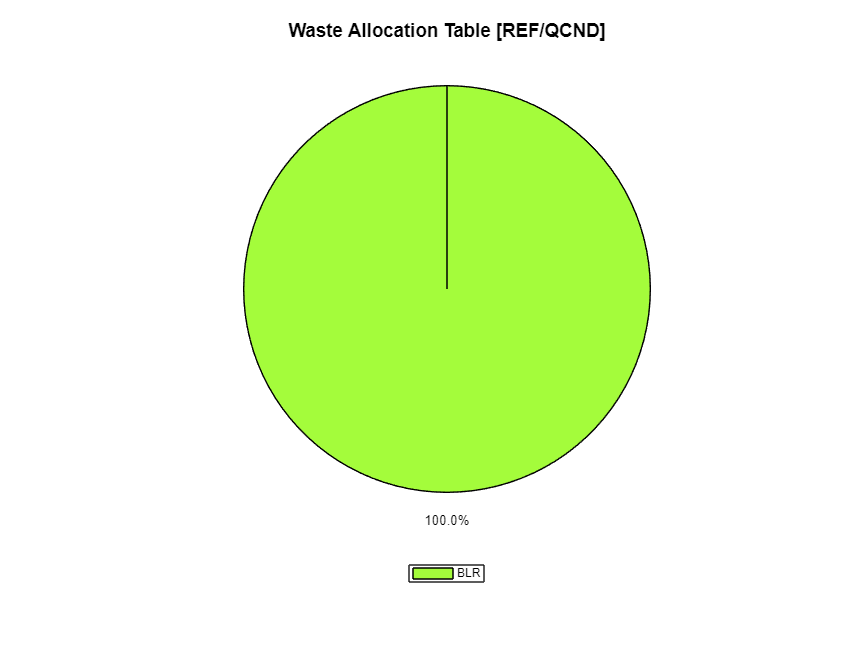

ShowGraph(model,'Graph',cType.Tables.WASTE_ALLOCATION);

#### Save the Results

Save the results into a file, using diferent file types

save=false;
type="xlsx";
if save
    filename=strcat("model_result.",type);
    SaveResults(model,filename);
end

#### **Summary Results**

Select the summary option

#### Select the summary results

Options=convertCharsToStrings(model.summaryOptions);
option=convertStringsToChars(Options(4));
model.setSummary(option);
res=model.summaryResults;

#### Show  Results

Show all available tables

showResults(res)


Flows Exergy (kW) - SUMMARY

 key            REF      TRB75     PBLR18      PCND2      PCND3      noIHE
———————————————————————————————————————————————————————————————————————————
 B1          83.570     89.430     83.930     87.640    108.000     83.570
 B2          17.900     19.540     18.460     21.920     41.990     17.900
 B3          15.790     16.940     16.390     19.590     38.680     17.900
 B4           5.784      6.190      6.011      6.340      9.990      5.784
 B5           7.877      8.430      7.948      8.528     12.620      7.877
 B6           9.420     10.310      9.471     10.330     15.490      7.877
 QBLR       100.000    106.300    100.800    103.500    120.200    106.900
 WP           2.447      2.619      2.264      2.554      3.053      2.447
 WN          50.000     50.000     50.000     50.000     50.000     50.000
 QCND        10.006     10.750     10.379     13.250     28.690     12.116


Process Unit Consumption (J/J) - SUMMARY

 key           REF      T

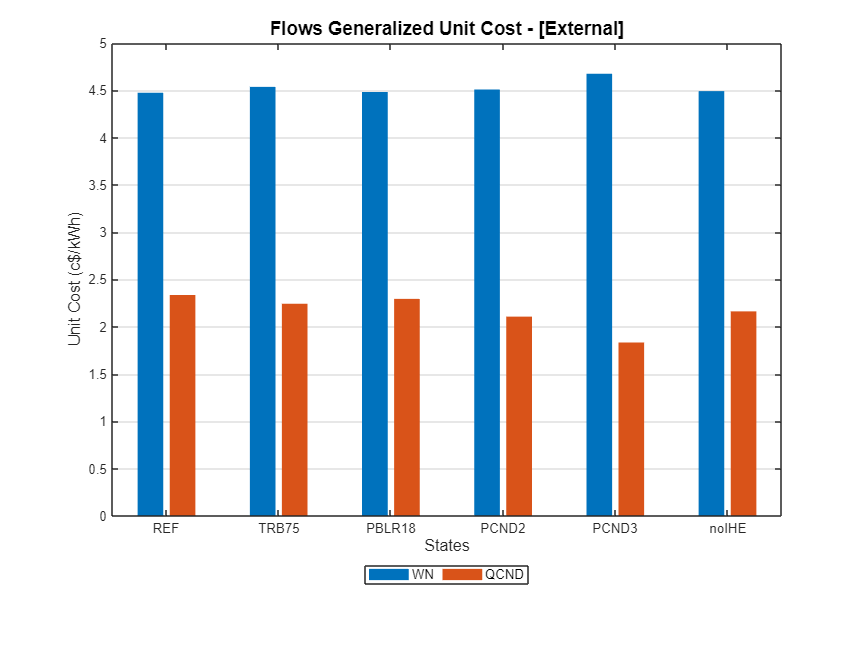

if model.isStateSummary
    showGraph(res,cType.Tables.SUMMARY_FLOW_GENERAL_UNIT_COST);
end

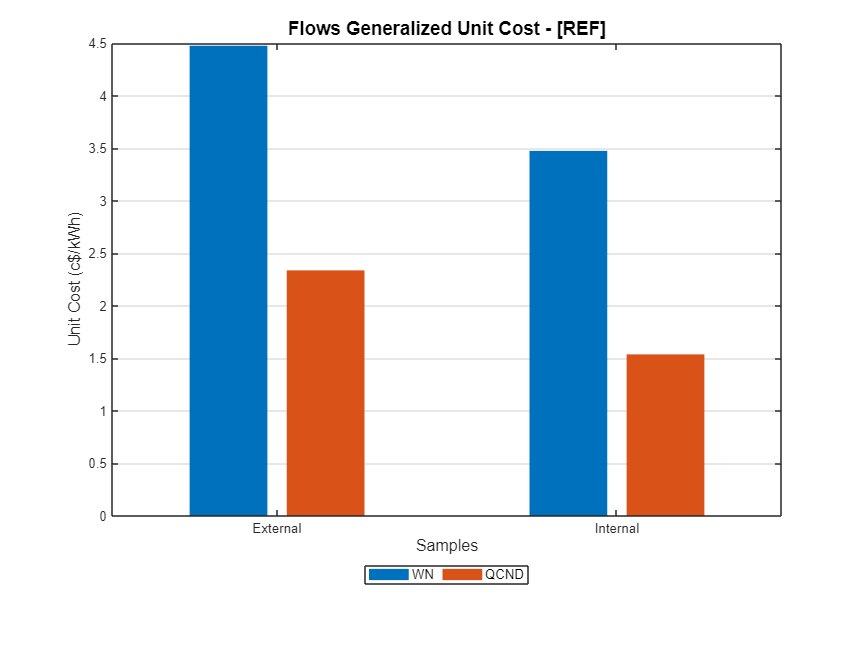

if model.isSampleSummary
    showGraph(res,cType.Tables.RSUMMARY_FLOW_GENERAL_UNIT_COST);
end

#### Diagnosis Analysis

Analyze a malfunction in the plant

States=convertCharsToStrings(model.StateNames);
state=convertStringsToChars(States(3));
model.setState(state);
model.summaryDiagnosis;

Fuel Impact:          0.8000 (kW)
Malfunction Cost:     0.8000 (kW)



showResults(model,cType.Tables.DIAGNOSIS);


Diagnosis Summary - PBLR18

Key        MF(kW)      ΔI(kW)      ΔR(kW)     ΔPt(kW)     MF*(kW)     MR*(kW)    ΔPt*(kW)
——————————————————————————————————————————————————————————————————————————————————————————
BLR        0.3817      0.4910      0.3730      0.0000      0.3817      0.5310      0.0000
TRB        0.0292     -0.0170      0.0000      0.0000     -0.0594     -0.0098      0.0000
IHE       -0.0128     -0.0200      0.0000      0.0000     -0.0209     -0.0035      0.0000
PMP       -0.0007     -0.0270      0.0000      0.0000     -0.0011     -0.0002      0.0000
CND        0.0000      0.0000      0.0000      0.0000     -0.0152     -0.0025      0.0000
ENV        0.3974      0.4270      0.3730      0.0000      0.2850      0.5150      0.0000



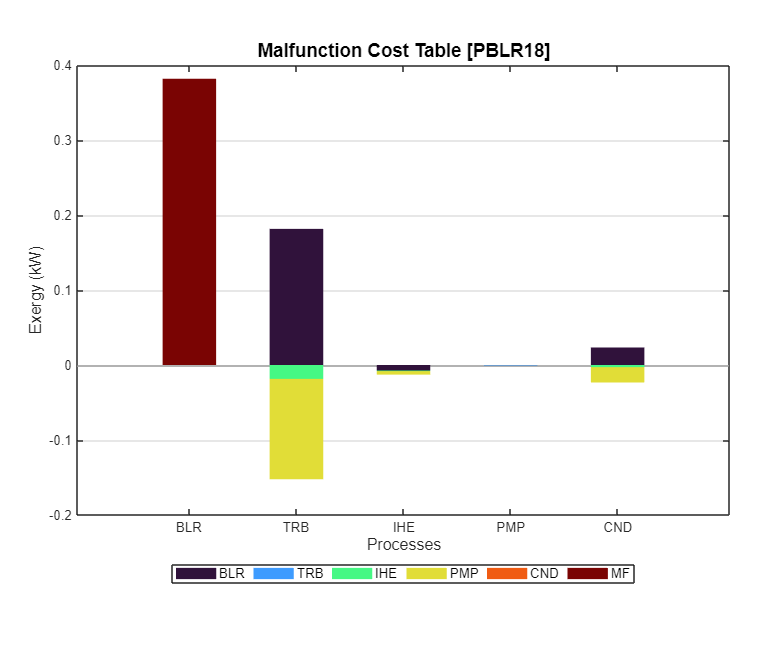

showGraph(model,cType.Tables.MALFUNCTION_COST,false);

#### **Recycling Analysis**

Select the model without IHE and analyse the capability of recycling

model.setRecycling(true);
setDiagnosisMethod(model,'NONE');
model.setState('noIHE');
showResults(model,cType.Tables.WASTE_RECYCLING_GENERAL);


Generalized Cost Recycling Analysis (c$/kWh) - [noIHE/]

 Recycle (%)            WN       QCND
——————————————————————————————————————
      0             4.4914     2.1635
     10             4.4400     2.1224
     20             4.3905     2.0829
     30             4.3428     2.0448
     40             4.2968     2.0080
     50             4.2524     1.9726
     60             4.2096     1.9384
     70             4.1682     1.9054
     80             4.1282     1.8734
     90             4.0896     1.8426
    100             4.0521     1.8127



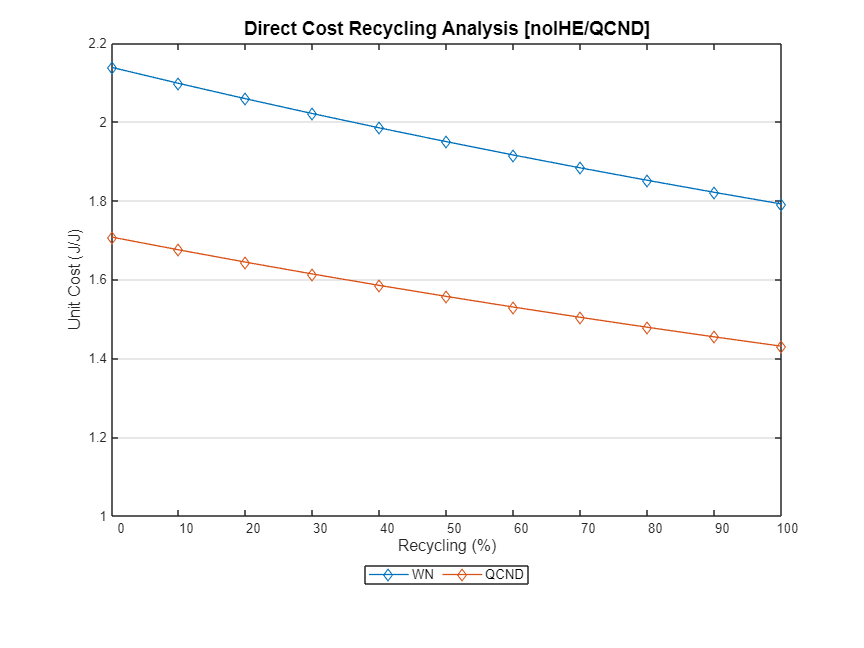

showGraph(model,cType.Tables.WASTE_RECYCLING_DIRECT);

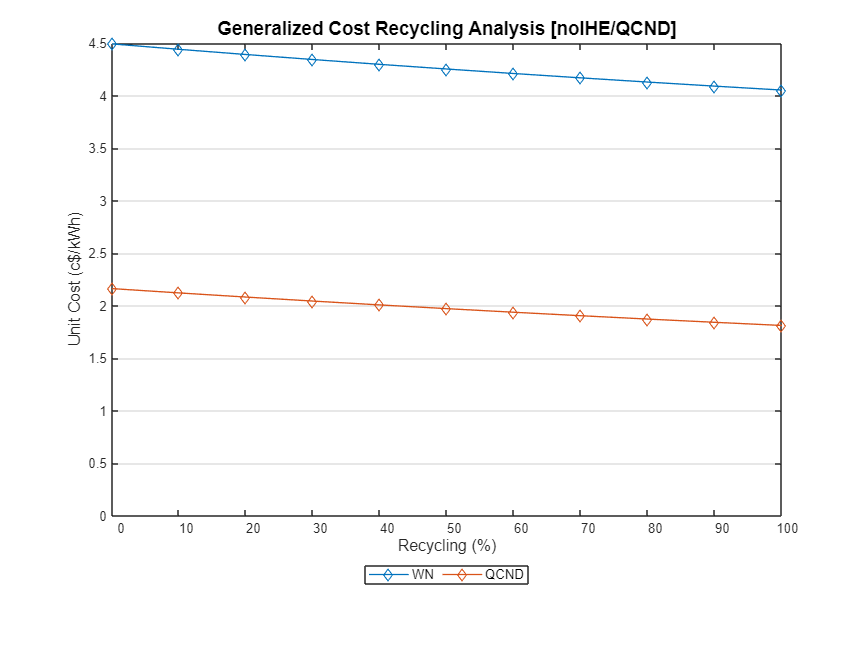

showGraph(model,cType.Tables.WASTE_RECYCLING_GENERAL);

#### Additional Help

help ThermoeconomicModel

 ThermoeconomicModel - Create a cThermoeconomicModel object from a data model file 
    This function creates a cThermoeconomicModel object. Once the object is created, all the
    public methods of the class could be used, allowing interactively obtaining all
    the results of a thermoeconomic analysis.
 
  Syntax
    model = ThermoeconomicModel(filename,Name,Value)
 
  Input Arguments
    filename - Name of the file with the data mode
 
  Name-Value Arguments
    ReferenceState - Reference state name. If it is not defined, first state is taken.
      char array | string
    State - Operation state name. If it is not defined, first state is taken.  
      char array | string
    ResourceSample - Resource Sample name. If it is not defined, first sample is taken
      char array | string
    CostTables - Cost Tables output
      'DIRECT' Direct Exergy Cost Tables only
      'GENERALIZED' Generalized Cost Tables only
      'ALL' - Both direct and genera